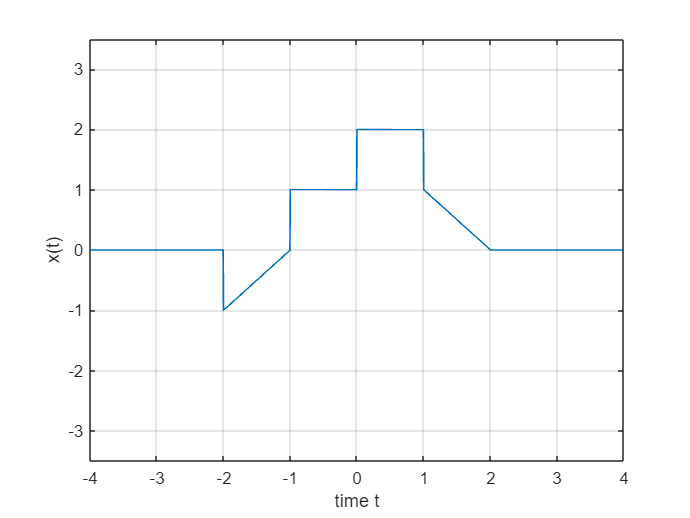

% Define the time values
t = -10:0.005:30; % Time values from -5 to 5 with a step of 0.01

% Create the unit step function
u = @(a) (a>=0);

p = @(t) (t+1).*(u(t+2)-u(t+1))+u(t+1)+u(t)-(t).*(u(t-1)-u(t-2))-2*u(t-2);

a = @(t) p(t-1);
b = @(t) p(2-t);
c = @(t) p(2*t+1);
d = @(t) p(4-t/2);
e = @(t) (p(t)+p(-t)).*u(t);

% Plot the function
plot(t,p(t),'LineWidth',1)
ylim([-3.5 3.50])
xlim([-4.00 4.00])
ylabel('x(t)')
xlabel('time t')
grid on

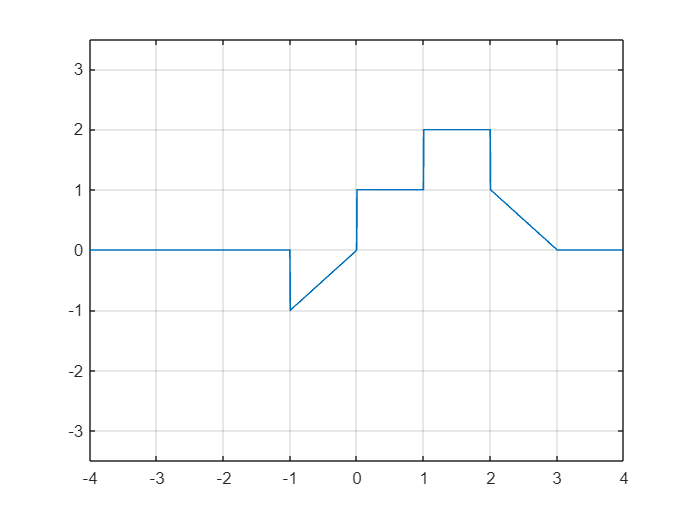


plot(t,a(t),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-4.00 4.00])
grid on

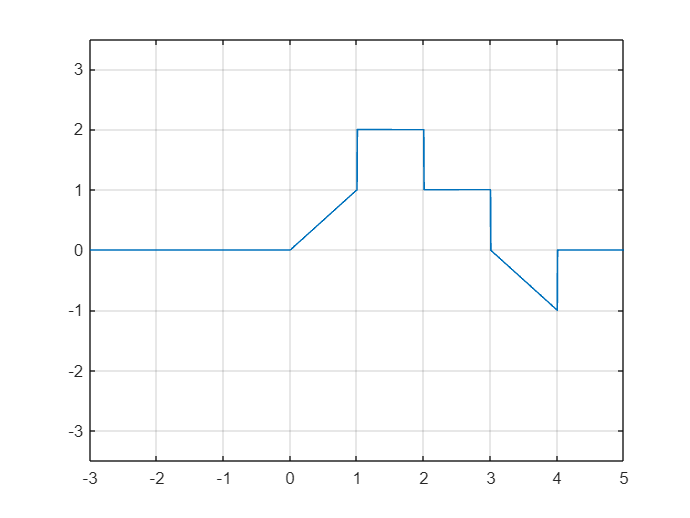


plot(t,b(t),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-3.00 5.00])
grid on

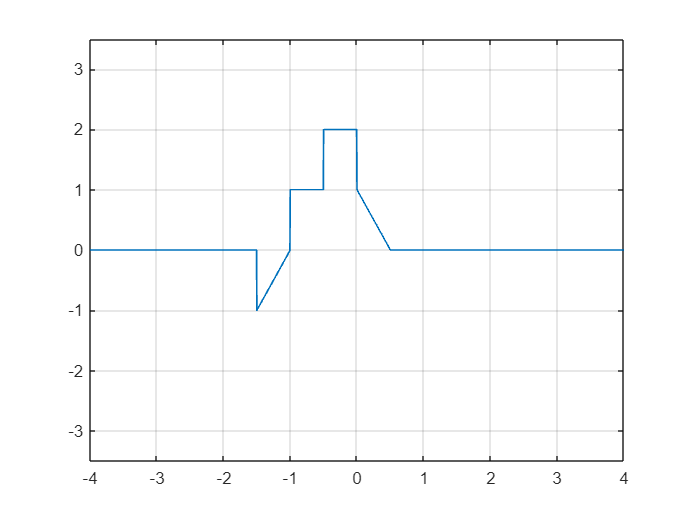


plot(t,c(t),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-4.00 4.00])
grid on

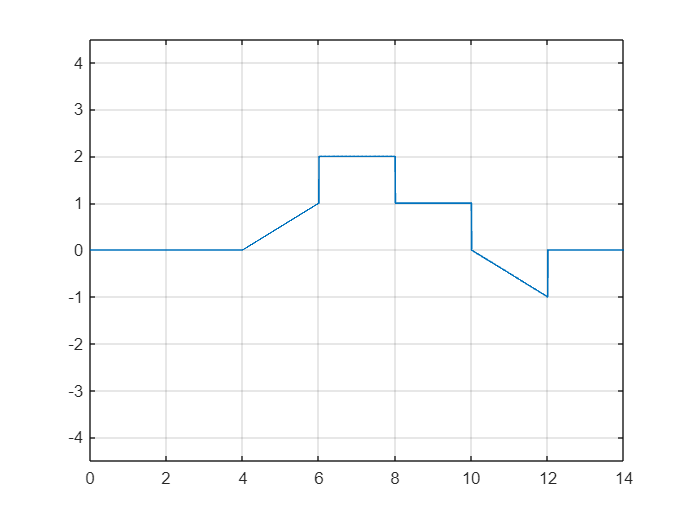


plot(t,d(t),'LineWidth',1)
ylim([-4.5 4.5])
xlim([-0.00 14.00])
grid on

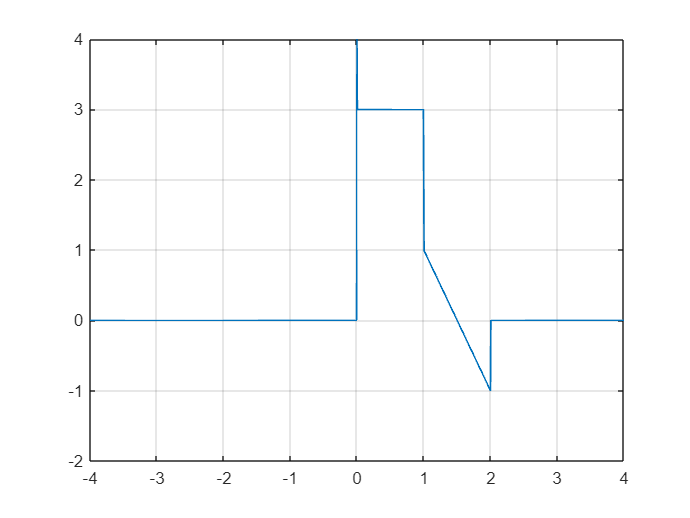


plot(t,e(t),'LineWidth',1)
ylim([-2 4])
xlim([-4.00 4.00])
grid on

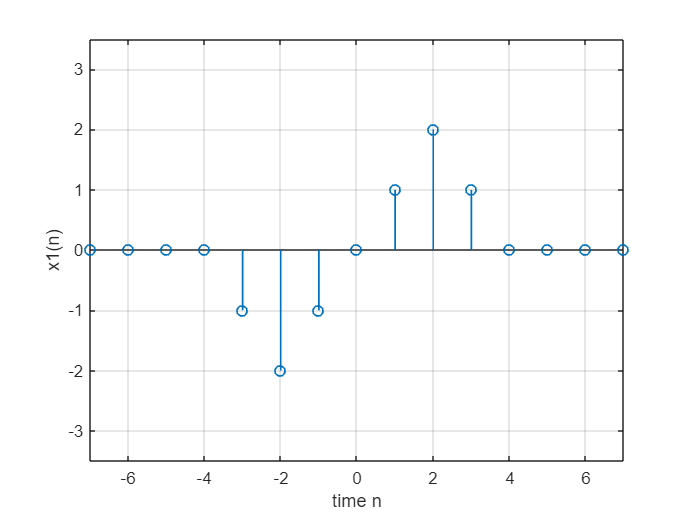


n = -40:1:40;
d = @(a) (a==0);

x1 = @(a) -d(a+3)-2*d(a+2)-d(a+1)+d(a-1)+2*d(a-2)+d(a-3);
x1e = @(a) (x1(a)+x1(-a))/2;
x1o = @(a) (x1(a)-x1(-a))/2;

stem(n,x1(n),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-7.00 7.00])
ylabel('x1(n)')
xlabel('time n')
grid on

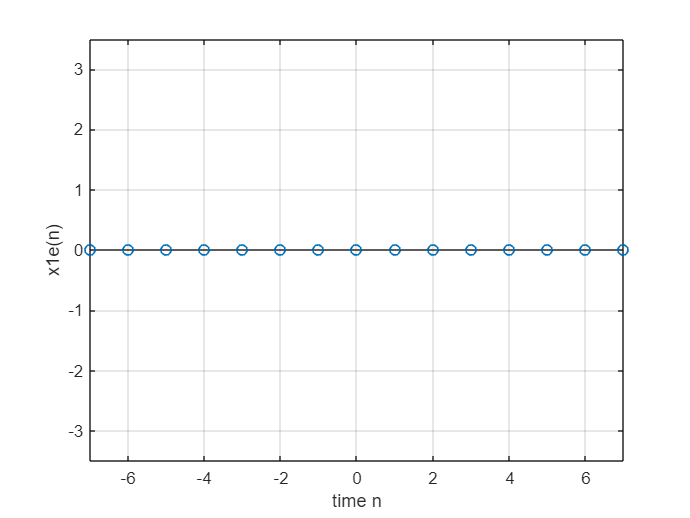


stem(n,x1e(n),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-7.00 7.00])
ylabel('x1e(n)')
xlabel('time n')
grid on

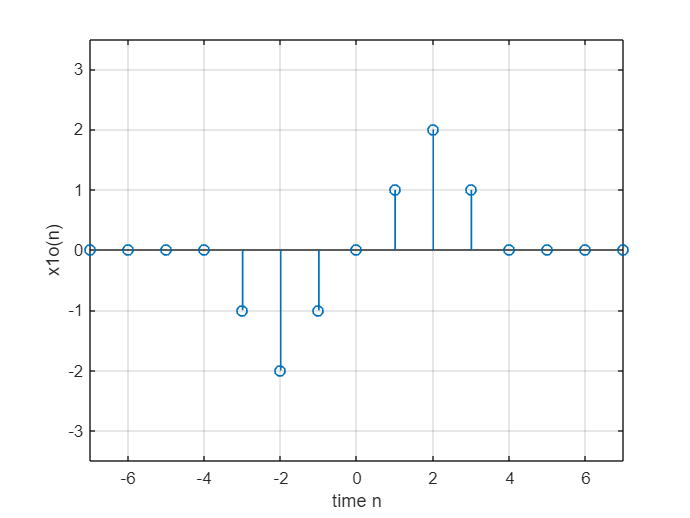


stem(n,x1o(n),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-7.00 7.00])
ylabel('x1o(n)')
xlabel('time n')
grid on